## Group assignment 10 - Ohm's law

You are given the assignment to verify Ohm’s law in the lab. In one form, Ohm’s Law states that voltage divided by resistance is equal to current:

U/R=I

You have a R=100`Ω `resistor, and measure the current going through the resistor at different voltages:

U = [-10,-5,0,5,10,15,20,25,30,35,40,45,50,55,60,65,70,75]

U =    -10    -5     0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75


% Added '-' in front of 3rd value which differs from the problem but is
% what the professor did to get the results 
I = [-0.118, -0.048, -0.011, 0.056, 0.088, 0.160, 0.215, 0.284, 0.296, 0.307, 0.383, 0.477, 0.479, 0.01, 0.03, 0.05,-0.01, 0.0]

I =    -0.1180   -0.0480   -0.0110    0.0560    0.0880    0.1600    0.2150    0.2840    0.2960    0.3070    0.3830    0.4770    0.4790    0.0100    0.0300    0.0500   -0.0100         0


1) Plot the data for voltage and current.

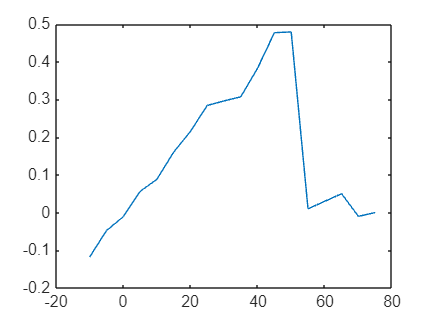

figure;
plot(U,I);

2) Formulate a hypothesis test based on Ohm's law for the slope.

To make Ohm's law look like a linear regression we instead show it as the following:


$$\frac{1}{R}*U=I\Rightarrow \alpha_0 +\beta_0 *x=y$$


We have 2 NULL hypotheses:


$$H_0 :\alpha_0 =0\;\&\;\beta_0 \;=\frac{1}{100}\;$$



$$H_a :{\alpha_0 \;\not= \;0\;\&\;\beta }_0 \;\not= \frac{1}{100}$$


3) Determine a linear model for the data (Slope and interception with the y-axis).

meanU = mean(U)

meanU = 32.5000

meanI = mean(I)

meanI = 0.1471


estB = sum(U.*I-meanU*meanI)/sum((U-meanU).^2)

estB = 0.0013


% a = y - bx
estA = meanI - estB*meanU

estA = 0.1053

4) Plot the linear model togehter with the data

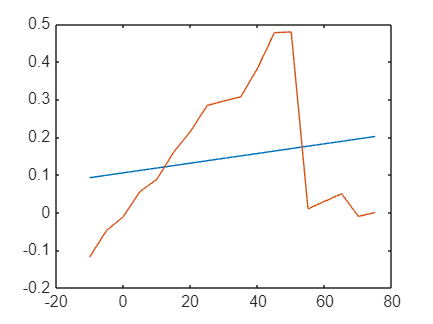

figure;
plot(U, estA+estB*U)
hold on;
plot(U,I)
hold off;

5) Can you reject the NULL hypothesis

sr2 = (1/(length(U)-2))*sum((I-meanI).^2)

sr2 = 0.0362

sxx = sum((U-meanU).^2)

sxx = 1.2112e+04


t = (estB - 1/100)/sqrt(sr2/sxx)

t = -5.0401


pval = 2*(1-tcdf(abs(double(t)), length(U)-2))

pval = 1.2072e-04

Since the P-value is lower than a (0.05) then we can reject the NULL hypothesis

6) Calculate the residuals and make the residual plot.

y = (estA+estB*U)

y =     0.0924    0.0989    0.1053    0.1117    0.1182    0.1246    0.1310    0.1375    0.1439    0.1503    0.1568    0.1632    0.1696    0.1761    0.1825    0.1889    0.1953    0.2018


residuals = I-y

residuals =    -0.2104   -0.1469   -0.1163   -0.0557   -0.0302    0.0354    0.0840    0.1465    0.1521    0.1567    0.2262    0.3138    0.3094   -0.1661   -0.1525   -0.1389   -0.2053   -0.2018


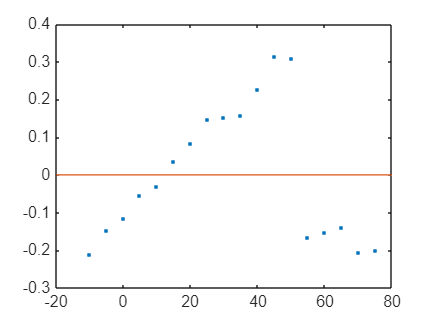

plot(U, residuals, '.', [-20 80], [0 0])

7) Based on the residual plot, is the linear model a good fit?

NO, it's very off from the linear regression

8) Find the 95% confidence interval for the estimate of the slope.

t0 = tinv(0.975, length(U)-2)

t0 = 2.1199


%alow = estA-t0*sqrt(sr2*(1/length(U)+(meanU.^2)/sxx))
%ahigh = estA+t0*sqrt(sr2*(1/length(U)+(meanU.^2)/sxx)) 

blow= estB-t0*sqrt(sr2/sxx)

blow = -0.0024

bhigh = estB+t0*sqrt(sr2/sxx)

bhigh = 0.0050

9) Based on the hypothesis test and the residual plot would you conclude that Ohm's law is true (that there is a linear connection between Voltage and Current)?

Purely based on the residual plot and hypothesis test we can't conclude that Ohm's law is true in regards to the values recorded in the experiment.

10) Are there any outliers in the experiment? Why is that?

We see that the last 5 values of I and U seem like outliers, so we will remove them to see of the hypothesis and residual test looks better.

11) Exclude outliers from the data set and repeat question 1-9.

We have removed the outliers and are redoing the previous questions.

newU = U(1:length(U)-5)

newU =    -10    -5     0     5    10    15    20    25    30    35    40    45    50


newI = I(1:length(I)-5)

newI =    -0.1180   -0.0480   -0.0110    0.0560    0.0880    0.1600    0.2150    0.2840    0.2960    0.3070    0.3830    0.4770    0.4790



meanU = mean(newU)

meanU = 20

meanI = mean(newI)

meanI = 0.1975


estB = sum(newU.*newI-meanU*meanI)/sum((newU-meanU).^2)

estB = 0.0100


% a = y - bx
estA = meanI - estB*meanU

estA = -0.0019

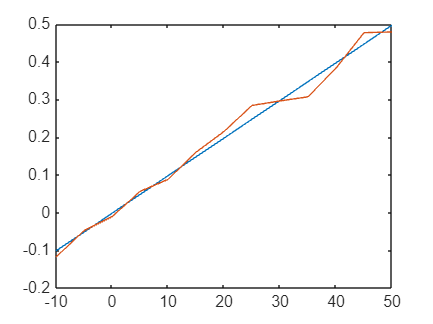


figure;
plot(newU, estA+estB*newU)
hold on;
plot(newU,newI)
hold off;


sr2 = (1/(length(newU)-2))*sum((newI-meanI).^2)

sr2 = 0.0416

sxx = sum((newU-meanU).^2)

sxx = 4550


t = (estB - 1/100)/sqrt(sr2/sxx)

t = -0.0087


pval = 2*(1-tcdf(abs(double(t)), length(newU)-2))

pval = 0.9932


y = (estA+estB*newU)

y =    -0.1017   -0.0518   -0.0019    0.0479    0.0978    0.1477    0.1975    0.2474    0.2973    0.3471    0.3970    0.4469    0.4967


residuals = newI-y

residuals =    -0.0163    0.0038   -0.0091    0.0081   -0.0098    0.0123    0.0175    0.0366   -0.0013   -0.0401   -0.0140    0.0301   -0.0177


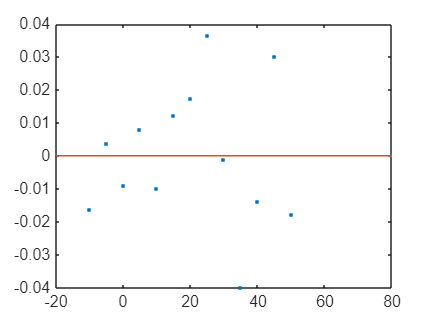

plot(newU, residuals, '.', [-20 80], [0 0])


t0 = tinv(0.975, length(newU)-2)

t0 = 2.2010


%alow = estA-t0*sqrt(sr2*(1/length(U)+(meanU.^2)/sxx))
%ahigh = estA+t0*sqrt(sr2*(1/length(U)+(meanU.^2)/sxx)) 

blow= estB-t0*sqrt(sr2/sxx)

blow = 0.0033

bhigh = estB+t0*sqrt(sr2/sxx)

bhigh = 0.0166

We can conclude that there is a way smaller residual by removing the "outliers" and our P-value is way above the 0.05 significance level